addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Comparing the natural spline to the not-a-knot spline

xData = [5 7 9]; 
yData = [5 2 4];

naturalSpline_1 = @(x) (5/32)*(x-5).^3 - (17/8)*(x-5) + 5;
naturalSpline_2 = @(x) (-5/32)*(x-7).^3 + (15/16)*(x-7).^2 - (1/4)*(x-7) + 2;

x1 = 5:0.01:7;
x2 = 7:0.01:9;
y1 = naturalSpline_1(x1);
y2 = naturalSpline_2(x2);

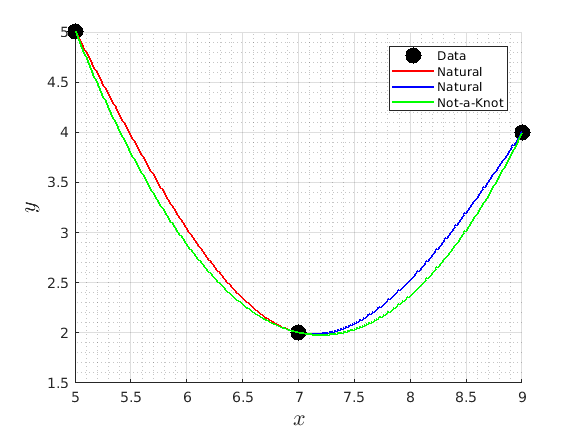


% Plot the data
figure(1); clf; hold on; grid on; grid minor
plot(xData, yData, 'k.', 'MarkerSize', 40)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 16)
%axis([4 10 1 6]);

% Plotting the natural spline
hold on;
plot(x1, y1, 'r-', 'LineWidth', 1.5);
plot(x2, y2, 'b-', 'LineWidth', 1.5);


% Plotting the not-a not spline
x3 = 5:0.01:9;
y3 = spline(xData, yData, x3);

hold on;
plot(x3, y3, 'g-', 'LineWidth', 1.5);
legend('Data', 'Natural', 'Natural', 'Not-a-Knot')
hold off;